Let's start by fixing the path


clear
clc

full_path='/storage/work/mjv5465/SAFE/';

restoredefaultpath;
addpath(genpath([full_path,'Data/']));
addpath(genpath([full_path,'Functions']));
addpath(genpath([full_path,'Scratch/']));
cd([full_path,'Scratch/']);

clear full_path  

## Let's start with long-run reversals (DeBondt and Thaler, 1985).

We'll replicate Table VI in Fama and French (1996), since that's the result that really sold the Fama and French (1993) three-factor model. 

clear
clc

load NYSE
load ret
load me
load dates
load ff

Next, we need to create the long-run reversal variables. The cookbook already creates these in makeCRSPDerivedVariables(), but it's easy enough to do that here too:

% Leave only NYSE stocks 
sortRet = ret;
sortRet(NYSE ~= 1) = nan;

% Create the sorting variables in a structure 
ppStruct(1).R = makePastPerformance(sortRet, 12, 1); 
ppStruct(1).label = {'12-2'};

ppStruct(2).R = makePastPerformance(sortRet, 24, 1); 
ppStruct(2).label = {'24-2'};

ppStruct(3).R = makePastPerformance(sortRet, 36, 1); 
ppStruct(3).label = {'36-2'};

ppStruct(4).R = makePastPerformance(sortRet, 48, 1); 
ppStruct(4).label = {'48-2'};

ppStruct(5).R = makePastPerformance(sortRet, 60, 1); 
ppStruct(5).label = {'60-2'};

ppStruct(6).R = makePastPerformance(sortRet, 60, 12);
ppStruct(6).label = {'60-13'};

Now let's run the sorts:

nPPVars = length(ppStruct);
for i = 1:nPPVars
    % Sort first
    ind = makeUnivSortInd(ppStruct(i).R, 10);
    
    
    % Run a bivariate sort (we'll need the GRS test for Table VII) for th
    % late sample first. For Table VI, you can run a univariate sort too
    [res, ~] =  runBivSort(ret, ind, 5, 2, dates, me, 'weighting', 'e', ...
                                                      'factorModel', 3, ...
                                                      'timePeriod', [193012 196306], ...
                                                      'printResults', 0, ...
                                                      'plotFigure', 0);
    resEarly(i,1) = res;
    
    % Late sample
    [res, ~] =  runBivSort(ret, ind, 5, 2, dates, me, 'weighting', 'e', ...
                                                      'factorModel', 3, ...
                                                      'timePeriod', [196306 199312], ...
                                                      'printResults', 0, ...
                                                      'plotFigure', 0);
    resLate(i,1) = res;
end

Print the results:

outputTable = [[resLate.xret] ...
               [resEarly.xret]]';
info.rnames = char([{''}; [ppStruct.label]'])

info = struct with fields:
    rnames: [7×5 char]


info.width = 160;

fprintf('Late sample results (07/1963 - 12/1993):\n');

Late sample results (07/1963 - 12/1993):


mprint(outputTable(1:nPPVars, :), info);

      
12-2     -0.1316     0.4348     0.5763     0.5471     0.7410     0.6492     0.8430     0.9092     1.0876     1.2611 
24-2      0.1883     0.5094     0.5737     0.6418     0.6887     0.7951     0.7602     0.7389     0.9629     1.0598 
36-2      0.2779     0.4793     0.6890     0.6569     0.7542     0.7525     0.7536     0.7339     0.8449     0.9760 
48-2      0.3895     0.6124     0.7265     0.7038     0.7141     0.7443     0.7101     0.7383     0.6856     0.8933 
60-2      0.5291     0.6342     0.6947     0.7569     0.7347     0.6971     0.7354     0.7087     0.7154     0.7123 
60-13     0.9929     0.7225     0.7589     0.6761     0.6383     0.7158     0.7080     0.6804     0.5855     0.4298 




fprintf('Early sample results (01/1931 - 06/1963):\n');

Early sample results (01/1931 - 06/1963):


mprint(outputTable(nPPVars+1:end, :),info);

      
12-2      1.4657     1.4589     1.2715     1.5179     1.3063     1.4800     1.4105     1.5336     1.5872     1.8866 
24-2      2.0409     1.6356     1.5686     1.5909     1.3668     1.4346     1.3310     1.2515     1.2357     1.4636 
36-2      2.2175     1.7350     1.6123     1.3935     1.3968     1.3613     1.3460     1.2455     1.2245     1.3858 
48-2      2.2076     1.7344     1.6518     1.5363     1.4529     1.3343     1.2711     1.2340     1.2857     1.2090 
60-2      2.3132     1.7848     1.6882     1.4469     1.4541     1.4038     1.2444     1.2016     1.2624     1.1205 
60-13     2.5039     1.7324     1.7321     1.5025     1.5634     1.2919     1.1563     1.2679     1.1216     1.0354 



Compare with FF96 Table VI:

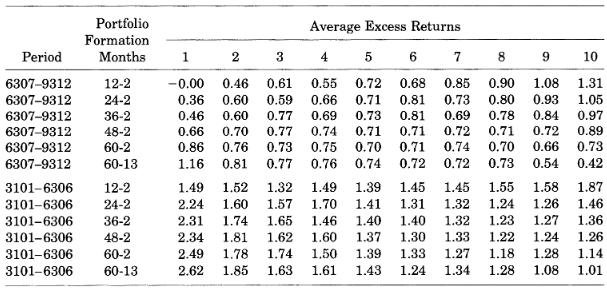

Now let's do Table 7. The results structure above should have all the results we need. Print the first panel first (t-12 to t-2):

clc

% Choose the first results structure (t-12 to t-2)
r = strcmp([ppStruct.label], {'12-2'});
res = resLate(r);

% Get the output table 
outputTable = [ res.alpha'; ...
               [res.factorLoadings.b]'; ...
                res.talpha'; ...
               [res.factorLoadings.t]'; ...
                res.r2'];

% Store the row names
info.rnames = char([{'','a','b','s','h','t(a)','t(b)','t(s)','t(h)','R^2'}]);
info.width = 160;

% Print
fprintf('Portfolio formation months are t-12 to t-2\n');

Portfolio formation months are t-12 to t-2


mprint(outputTable, info);

     
a       -1.2031    -0.3791    -0.2081    -0.1704     0.0197    -0.0345     0.1671     0.2578     0.4054     0.6078 
b        1.1326     1.0402     1.0417     1.0178     1.0209     1.0130     1.0289     1.0289     1.0814     1.1088 
s        1.3437     0.7990     0.6457     0.5571     0.5247     0.4480     0.4346     0.4346     0.4801     0.6346 
h        0.4747     0.3323     0.3614     0.2915     0.3169     0.2894     0.2659     0.2118     0.2026     0.0172 
t(a)    -5.5873    -3.0090    -2.0912    -2.1453     0.2857    -0.6348     2.7730     4.0714     4.8802     4.8072 
t(b)    21.1515    33.2001    42.0943    51.5374    59.4163    75.0354    68.6715    65.3524    52.3503    35.2638 
t(s)    17.1411    17.4198    17.8235    19.2694    20.8611    22.6661    19.8151    18.8577    15.8758    13.7870 
t(h)     5.4736     6.5490     9.0162     9.1140    11.3882    13.2347    10.9559     8.3069     6.0563     0.3371 
R^2      0.7601     0.8542     0.8939     0.9239     0.9401     0.

fprintf('GRS statistic is %2.4f, and its p-value is %2.4f.\n', res.grsFstat(1), res.grsPval(1));

GRS statistic is 5.8244, and its b-value is 0.0000.


Compare with:

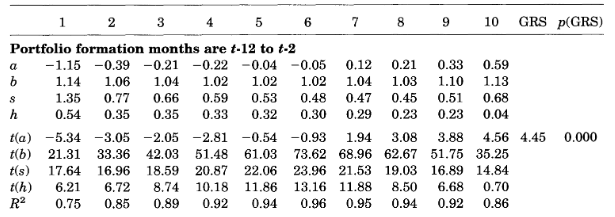

Now do the second panel (t-48 to t-2):

clc

% Choose the fourth results structure (t-48 to t-2)
r = strcmp([ppStruct.label], {'48-2'});
res = resLate(r);

% Get the output table 
outputTable = [ res.alpha'; ...
               [res.factorLoadings.b]'; ...
                res.talpha'; ...
               [res.factorLoadings.t]'; ...
                res.r2'];

% Store the row names
info.rnames = char([{'','a','b','s','h','t(a)','t(b)','t(s)','t(h)','R^2'}]);
info.width = 160;

% Print
fprintf('Portfolio formation months are t-12 to t-2\n');

Portfolio formation months are t-12 to t-2


mprint(outputTable, info);

     
a       -0.9269    -0.3577    -0.1092    -0.0445    -0.0038     0.0755     0.0802     0.1665     0.1554     0.4263 
b        1.1718     1.1141     1.0809     1.0173     1.0217     1.0084     1.0031     0.9883     1.0268     1.0824 
s        1.6265     0.9585     0.6808     0.5834     0.5025     0.4147     0.3834     0.3615     0.3780     0.4128 
h        0.8017     0.5086     0.4164     0.3436     0.3228     0.2816     0.2201     0.1195    -0.0181    -0.2307 
t(a)    -3.8459    -3.2107    -1.2229    -0.5786    -0.0576     1.3350     1.3869     2.6318     2.2512     4.4809 
t(b)    19.5519    40.2176    48.6635    53.1694    61.4368    71.6837    69.7262    62.8175    59.7972    45.7544 
t(s)    18.5381    23.6348    20.9348    20.8277    20.6405    20.1358    18.2069    15.6941    15.0364    11.9203 
t(h)     8.2594    11.3360    11.5744    11.0871    11.9848    12.3592     9.4466     4.6908    -0.6514    -6.0220 
R^2      0.7540     0.9002     0.9185     0.9287     0.9429     0.

fprintf('GRS statistic is %2.4f, and its b-value is %2.4f.\n', res.grsFstat(1), res.grsPval(1));

GRS statistic is 3.8089, and its b-value is 0.0001.


Compare with:

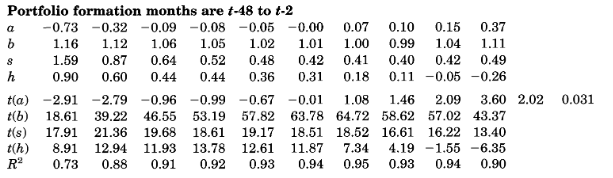

And finally the third, last panel:

clc

% Choose the last results structure (t-60 to t-13)
r = strcmp([ppStruct.label], {'60-13'});
res = resLate(r);

% Get the output table 
outputTable = [ res.alpha'; ...
               [res.factorLoadings.b]'; ...
                res.talpha'; ...
               [res.factorLoadings.t]'; ...
                res.r2'];

% Store the row names
info.rnames = char([{'','a','b','s','h','t(a)','t(b)','t(s)','t(h)','R^2'}]);
info.width = 160;

% Print
fprintf('Portfolio formation months are t-60 to t-13\n');

Portfolio formation months are t-60 to t-13


mprint(outputTable, info);

     
a       -0.2678    -0.2204    -0.0674    -0.1000    -0.0741     0.0592     0.0585     0.0868     0.0290    -0.0567 
b        1.1404     1.1078     1.0806     1.0342     1.0051     0.9822     1.0123     1.0044     1.0361     1.1131 
s        1.5292     0.9139     0.7087     0.6267     0.5376     0.4693     0.3614     0.3492     0.3851     0.4006 
h        0.7688     0.4821     0.3784     0.3621     0.3040     0.2449     0.2686     0.1605     0.0267    -0.2085 
t(a)    -1.2381    -2.3879    -0.8495    -1.3863    -1.1998     1.0255     0.9730     1.4050     0.4478    -0.7393 
t(b)    21.2018    48.2761    54.8064    57.6257    65.4737    68.4290    67.6772    65.3790    64.2626    58.3428 
t(s)    19.4197    27.2052    24.5524    23.8543    23.9222    22.3331    16.5040    15.5283    16.3145    14.3438 
t(h)     8.8245    12.9721    11.8488    12.4560    12.2268    10.5351    11.0856     6.4511     1.0225    -6.7460 
R^2      0.7772     0.9270     0.9361     0.9399     0.9509     0.

fprintf('GRS statistic is %2.4f, and its b-value is %2.4f.\n', res.grsFstat(1), res.grsPval(1));

GRS statistic is 1.4106, and its b-value is 0.1736.


Compare with: 

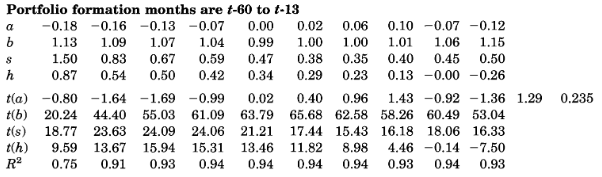

A much easier way to see that long-run reversals are explain by the three-factor model is just to do a spanning test:

clear
clc

load ret
load NYSE
load dates
load me
load bm

% Pick the sorting specifications
nPtf = 5;
weighting = 'e';
timePeriod = 196306;

R6013 = makePastPerformance(ret, 60, 12);
indR6013 = makeUnivSortInd(-R6013, nPtf, NYSE);
resR6013 = runUnivSort(ret, indR6013, dates, me, 'weighting', weighting, ...
                                                 'timePeriod', timePeriod);

     ---------------------------------------------------------------------------- 
              Equally-weighted  portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                      
              1    0.511   -0.061    1.038    0.643   -0.081    -0.183
                 [ 2.31]  [-1.13]  [82.09]  [35.55]  [-4.36]  [-14.11]
                                                                      
              2    0.748    0.126    0.905    0.585    0.217    -0.102
                 [ 4.01]  [ 2.97]  [91.34]  [41.23]  [14.96]  [-10.03]
                                                                      
              3    0.716    0.083    0.886    0.660    0.278    -0.118
                 [ 3.80] 


indBM = makeUnivSortInd(bm, nPtf, NYSE);
resBM = runUnivSort(ret, indBM, dates, me, 'weighting', weighting, ...
                                           'timePeriod', timePeriod);

     ---------------------------------------------------------------------------- 
              Equally-weighted  portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
              1    0.401   -0.157    1.066    0.944    -0.290    -0.222
                 [ 1.54]  [-1.96]  [56.90]  [35.21]  [-10.59]  [-11.54]
                                                                       
              2    0.691    0.088    0.977    0.800    0.053    -0.187 
                 [ 3.14]  [ 1.65]  [78.43]  [44.87]  [ 2.90]  [-14.61] 
                                                                       
              3    0.849    0.176    0.944    0.770    0.302    -0.150 
                 


indMe = makeUnivSortInd(-me, nPtf, NYSE);
resMe = runUnivSort(ret, indMe, dates, me, 'weighting', weighting, ...
                                           'timePeriod', timePeriod);

     ---------------------------------------------------------------------------- 
              Equally-weighted  portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                      
              1    0.569   -0.017     1.011   -0.012    0.052   -0.003
                 [ 3.36]  [-0.65]  [169.88]  [-1.43]  [ 6.01]  [-0.53]
                                                                      
              2    0.672    0.004     1.055    0.341    0.107   -0.040
                 [ 3.47]  [ 0.09]  [115.03]  [26.00]  [ 7.99]  [-4.20]
                                                                      
              3    0.732    0.005     1.058    0.644    0.144   -0.055
                 [ 3.46] 



retR6013 = resR6013.pret(:, end);
retBM = resBM.pret(:, end);
retMe = resMe.pret(:, end);
const = 0.01*ones(size(retR6013));

prt(nanols(retR6013,[const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0016 
Durbin-Watson  =    1.6563 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.522999         3.576544         0.000371 



prt(nanols(retR6013,[const retBM retMe]))

Ordinary Least-squares Estimates 
R-squared      =    0.6616 
Rbar-squared   =    0.6606 
sigma^2        =    0.0005 
Durbin-Watson  =    1.6925 
Nobs, Nvars    =    726,     3 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.142107         1.621480         0.105351 
variable 2         0.268027        10.760579         0.000000 
variable 3         0.664380        35.463399         0.000000 



or run a FamaMacBeth regression:

runFamaMacBeth(100*ret, -R6013, dates, 'timePeriod', timePeriod);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.335        5.372 
                    var 1        0.195        3.359 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [-R6013 log(me) log(bm)], dates, 'timePeriod', timePeriod);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.699        4.937 
                    var 1        0.084        2.304 
                    var 2       -0.081       -2.097 
                    var 3        0.243        3.923 

---------------------------------------------------------------------- 


## Let's look at momentum now

Start with the classic momentum result:

clear
clc

load ret
load dates
load me
load NYSE
load ff

nPtf = 5;
timePeriod = 196306;

R122 = makePastPerformance(ret, 12, 1);
indR122 = makeUnivSortInd(R122, 10, NYSE);
resR122 = runUnivSort(ret, indR122, dates, me, 'weighting', 'v', ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);


Now let's do that for the recent and intermediate past performance:

% intermediate
R127 = makePastPerformance(ret, 12, 6);
indR127 = makeUnivSortInd(R127, 10, NYSE);
resR127 = runUnivSort(ret, indR127, dates, me, 'weighting', 'v', ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);

% Recent
R62 = makePastPerformance(ret, 6, 1);
indR62 = makeUnivSortInd(R62, 10, NYSE);
resR62 = runUnivSort(ret, indR62, dates, me, 'weighting', 'v', ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);

Store the long/short return series and compare their performance:

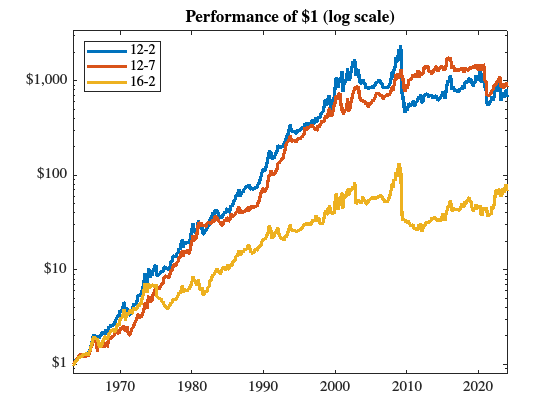

ret122 = resR122.pret(:, end);
ret127 = resR127.pret(:, end);
ret62 = resR62.pret(:, end);

figure;
ibbots([ret122 ret127 ret62], dates, 'timePeriod', timePeriod, ...
                                     'legendLabels', {'12-2','12-7','16-2'});

Now let's replicate Novy-Marx (2012) Table 2. Determine the sample:

s = find(dates==192701);
e = find(dates==201012);
const(1:s-1) = nan;
const(e+1:end) = nan;

Next let's run the regressions corresponding to the columns in the table:

% These correspond to columns
res(1, 1) = nanols(ret127, const);
res(2, 1) = nanols(ret127, [const mkt]);
res(3, 1) = nanols(ret127, [const ff3(:, 2:end)]);
res(4, 1) = nanols(ret127, [const ff4(:, 2:end)]);
res(5, 1) = nanols(ret62, const);
res(6, 1) = nanols(ret62, [const mkt]);
res(7, 1) = nanols(ret62, [const ff3(:, 2:end)]);
res(8, 1) = nanols(ret62, [const ff4(:, 2:end)]);

Print the results:

coefs = nan(6, 8);
tstats = nan(6, 8);

for i = 1:length(res)
    for j = 1:length(res(i).beta)
        coefs(j, i) = res(i).beta(j);
        tstats(j, i) = res(i).tstat(j)
    end
    coefs(end, i) = res(i).rbar;
end

tstats =     5.6506       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759       NaN       NaN       NaN       NaN       NaN       NaN
       NaN   -7.9220       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118       NaN       NaN       NaN       NaN       NaN
       NaN   -7.9220       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118       NaN       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118       NaN       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118       NaN       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907       NaN       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907       NaN       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907       NaN       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168       NaN       NaN       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683       NaN       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN       NaN       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998       NaN       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029       NaN       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN       NaN       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670       NaN
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN   -7.9463       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670   -0.7676
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334       NaN
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN   -7.9463       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670   -0.7676
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334   -5.7282
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227       NaN
       NaN       NaN  -12.8782   -5.2254       NaN       NaN   -7.9463       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670   -0.7676
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334   -5.7282
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227   -3.8627
       NaN       NaN  -12.8782   -5.2254       NaN       NaN   -7.9463       NaN
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670   -0.7676
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334   -5.7282
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227   -3.8627
       NaN       NaN  -12.8782   -5.2254       NaN       NaN   -7.9463    2.3477
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


tstats =     5.6506    6.6759    8.3118    3.9168    2.6683    4.3998    5.3670   -0.7676
       NaN   -7.9220   -4.8470    1.2695       NaN  -13.5029  -10.0334   -5.7282
       NaN       NaN    0.0907    1.0785       NaN       NaN   -3.2227   -3.8627
       NaN       NaN  -12.8782   -5.2254       NaN       NaN   -7.9463    2.3477
       NaN       NaN       NaN   31.8578       NaN       NaN       NaN   37.3102
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN



% mat2Tex(coefs, tstats, {'Intercept','MKT','SMB','HML','UMD','Adj. R^2'})
info.rnames = char({'','Intercept','MKT','SMB','HML','UMD','Adj. R^2'});
mprint(coefs, info);

          
Intercept     1.1753     1.3564     1.5730     0.5381     0.6279     0.9592     1.1344    -0.1081 
MKT              NaN    -0.2912    -0.1788     0.0341        NaN    -0.5327    -0.4134    -0.1578 
SMB              NaN        NaN     0.0055     0.0461        NaN        NaN    -0.2178    -0.1691 
HML              NaN        NaN    -0.6915    -0.2129        NaN        NaN    -0.4765     0.0981 
UMD              NaN        NaN        NaN     0.9957        NaN        NaN        NaN     1.1954 
Adj. R^2      0.0000     0.0578     0.1899     0.5970     0.0000     0.1526     0.2107     0.6691 



mprint(tstats, info);

          
Intercept     5.6506     6.6759     8.3118     3.9168     2.6683     4.3998     5.3670    -0.7676 
MKT              NaN    -7.9220    -4.8470     1.2695        NaN   -13.5029   -10.0334    -5.7282 
SMB              NaN        NaN     0.0907     1.0785        NaN        NaN    -3.2227    -3.8627 
HML              NaN        NaN   -12.8782    -5.2254        NaN        NaN    -7.9463     2.3477 
UMD              NaN        NaN        NaN    31.8578        NaN        NaN        NaN    37.3102 
Adj. R^2         NaN        NaN        NaN        NaN        NaN        NaN        NaN        NaN 



Compare with:

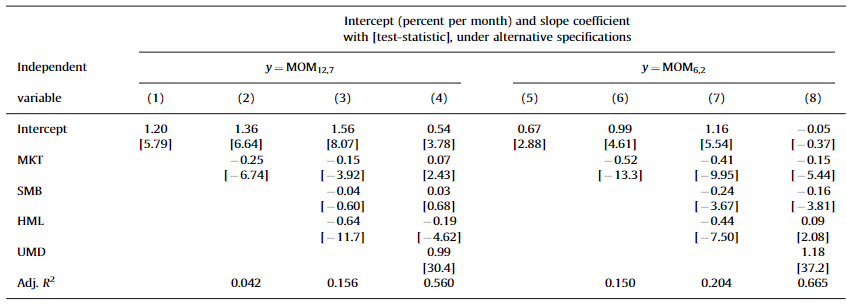

While we are at momentum, it's worth looking at its relationship with fundamental momentum, i.e., PEAD:

clear
clc

load ret
load NYSE
load dates
load me
load CAR3 % Can use SUE here

% Pick the sorting specifications
nPtf = 10;
weighting = 'v';
timePeriod = 197306;

R122 = makePastPerformance(ret, 12, 1);
indR122 = makeUnivSortInd(R122, nPtf, NYSE);
resR122 = runUnivSort(ret, indR122, dates, me, 'weighting', weighting, ...
                                                 'timePeriod', timePeriod);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
               1    0.015   -0.340    1.243    0.558   -0.049    -0.956
                  [ 0.04]  [-2.55]  [41.36]  [12.65]  [-1.11]  [-31.09]
                                                                       
               2    0.459    0.110    1.082    0.188    0.035    -0.697
                  [ 1.69]  [ 1.54]  [67.08]  [ 7.92]  [ 1.50]  [-42.26]
                                                                       
               3    0.635    0.239    0.994    0.028    0.134    -0.506
                  [ 


indCAR3 = makeUnivSortInd(CAR3, nPtf, NYSE);
resCAR3 = runUnivSort(ret, indCAR3, dates, me, 'weighting', weighting, ...
                                           'timePeriod', timePeriod);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
               1    0.152   -0.532    1.218    0.356   -0.051    -0.253
                  [ 0.56]  [-5.70]  [57.94]  [11.53]  [-1.68]  [-11.75]
                                                                       
               2    0.563   -0.087    1.096    0.042    0.070   -0.128 
                  [ 2.54]  [-1.30]  [72.25]  [ 1.90]  [ 3.16]  [-8.26] 
                                                                       
               3    0.572   -0.023    0.967   -0.027    0.066   -0.053 
                  [ 



retR122 = resR122.pret(:, end);
retCAR3 = resCAR3.pret(:, end);
const = 0.01*ones(size(retR122));

prt(nanols(retR122,[const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0055 
Durbin-Watson  =    1.9077 
Nobs, Nvars    =    606,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         1.013973         3.351547         0.000854 



prt(nanols(retCAR3,[const]))

Ordinary Least-squares Estimates 
R-squared      =   -0.0000 
Rbar-squared   =   -0.0000 
sigma^2        =    0.0011 
Durbin-Watson  =    2.0809 
Nobs, Nvars    =    606,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.925410         6.993602         0.000000 




prt(nanols(retR122,[const retCAR3]))

Ordinary Least-squares Estimates 
R-squared      =    0.1816 
Rbar-squared   =    0.1803 
sigma^2        =    0.0045 
Durbin-Watson  =    1.8810 
Nobs, Nvars    =    606,     2 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.112216         0.394059         0.693676 
variable 2         0.974441        11.578548         0.000000 



prt(nanols(retCAR3,[const retR122]))

Ordinary Least-squares Estimates 
R-squared      =    0.1816 
Rbar-squared   =    0.1803 
sigma^2        =    0.0009 
Durbin-Watson  =    2.0543 
Nobs, Nvars    =    606,     2 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.736399         6.090521         0.000000 
variable 2         0.186406        11.578548         0.000000 



## Let's look at industry momentum next

The cookbook actually creates an industry return variable based on the FF49 industries. That is done in the makeCRSPDerivedVariables() function. The variable is called ireta and it assigned to every (month, permno) cell the return corresponding to FF49 industry the company is classified into that month. 

clear
clc

load ret
load iFF49reta
load ff
load iFF49ret
load dates
load me
load NYSE
load R
load SIC

nPtf = 10;

% This will make the 12-2 based on the industry returns 
iR122 = makePastPerformance(iFF49reta, 12, 1);

% Let sort on the 12-2 industry return
indIR122 = makeUnivSortInd(iR122, nPtf, NYSE);
resIR122 = runUnivSort(ret, indIR122, dates, me);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
               1    0.415    0.020    1.075    0.095   -0.052    -0.530
                  [ 1.87]  [ 0.24]  [65.03]  [ 3.59]  [-2.12]  [-27.50]
                                                                       
               2    0.504    0.016    1.029   -0.089    0.119    -0.377
                  [ 2.46]  [ 0.19]  [60.04]  [-3.27]  [ 4.72]  [-18.87]
                                                                       
               3    0.611    0.120    0.987   -0.005    0.047    -0.280
                  [ 


% And on past month's industry return
indIR10 = makeUnivSortInd(iFF49reta, nPtf, NYSE);
resIR10 = runUnivSort(ret, indIR10, dates, me);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                      
               1    0.205   -0.418    1.020    0.206   -0.137   -0.112
                  [ 1.03]  [-3.87]  [47.00]  [ 5.95]  [-4.27]  [-4.43]
                                                                      
               2    0.366   -0.309    1.026    0.040   -0.028   -0.021
                  [ 2.04]  [-3.74]  [61.81]  [ 1.43]  [-1.12]  [-1.07]
                                                                      
               3    0.576   -0.068    1.015   -0.004    0.012   -0.049
                  [ 3.22]  [

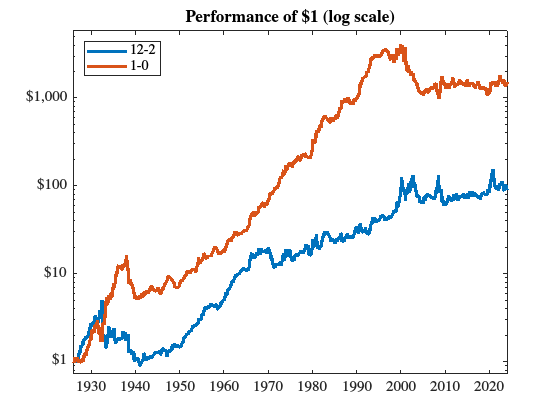


% Store the long/short strategies
retIR122 = resIR122.pret(:, end);
retIR10 = resIR10.pret(:, end);

% Plot them
figure;
ibbots([retIR122 retIR10], dates, 'legendLabels',{'12-2','1-0'});

Let's see if it's a distinct effect from regular momentum using spanning tests:

R122 = makePastPerformance(ret, 12, 1);
indR122 = makeUnivSortInd(R122, nPtf, NYSE);
resR122 = runUnivSort(ret, indR122, dates, me, 'weighting', 'v', ...
                                               'printResults', 0, ...
                                               'plotFigure', 0);

retR122 = resR122.pret(:, end);
const = 0.01*ones(size(retR122));

prt(nanols(retIR10,[const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0031 
Durbin-Watson  =    2.0971 
Nobs, Nvars    =   1170,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.780813         4.786675         0.000002 



prt(nanols(retIR10,[const retR122]))

Ordinary Least-squares Estimates 
R-squared      =    0.0051 
Rbar-squared   =    0.0043 
sigma^2        =    0.0031 
Durbin-Watson  =    2.0724 
Nobs, Nvars    =   1160,     2 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.720528         4.356205         0.000014 
variable 2         0.050935         2.443802         0.014682 




prt(nanols(retR122,[const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0062 
Durbin-Watson  =    1.8449 
Nobs, Nvars    =   1165,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         1.133941         4.934400         0.000001 



prt(nanols(retR122,[const retIR10]))

Ordinary Least-squares Estimates 
R-squared      =    0.0051 
Rbar-squared   =    0.0043 
sigma^2        =    0.0061 
Durbin-Watson  =    1.8317 
Nobs, Nvars    =   1160,     2 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         1.048339         4.509494         0.000007 
variable 2         0.100734         2.443802         0.014682 



And here is a closer replication of Moskowtiz and Grinblatt (1999);

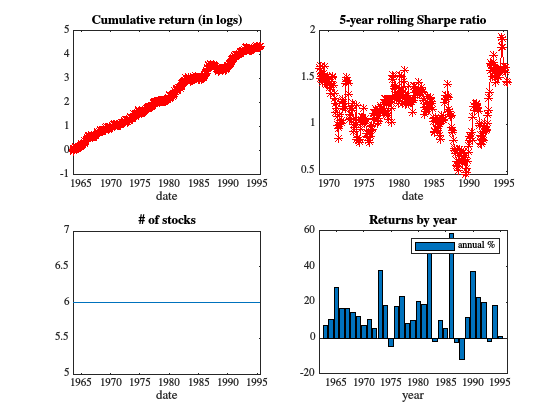

     ---------------------------------------------------------------------------- 
              Equally-weighted  portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                     
              1   -0.151   -0.526    1.036    0.205   -0.007   -0.161
                 [-0.56]  [-4.38]  [35.89]  [ 4.81]  [-0.15]  [-4.70]
                                                                     
              2    0.403    0.010    1.015    0.191    0.023   -0.139
                 [ 1.60]  [ 0.12]  [48.38]  [ 6.17]  [ 0.67]  [-5.60]
                                                                     
              3    1.053    0.319    1.035    0.092    0.192    0.201
                 [ 4.13]  [ 2.84]


load SIC
SIC = floor(SIC/100);
SIC(isnan(SIC)) = 0;
indMG = 1  * (SIC>=10 & SIC<=14) + ...
        2  * (SIC==20) + ...
        3  * (SIC>=22 & SIC<=23) + ...
        4  * (SIC==26) + ...
        5  * (SIC==28) + ...
        6  * (SIC==29) + ...
        7  * (SIC==32) + ...
        8  * (SIC==33) + ...
        9  * (SIC==34) + ...
        10 * (SIC==35) + ...
        11 * (SIC==36) + ...
        12 * (SIC==37) + ...
        13 * (SIC>=38 & SIC<=39) + ...
        14 * (SIC==40) + ...
        15 * (SIC>=41 & SIC<=47) + ...
        16 * (SIC==49) + ...
        17 * (SIC==53) + ...
        18 * ((SIC>=50 & SIC<=52) | (SIC>=54 & SIC<=59)) + ...
        19 * (SIC>=60 & SIC<=69);

indMG(indMG==0 & SIC>0) = 20;

res = runUnivSort(ret, indMG, dates,me, 'weighting', 'v', ...
                                      'timePeriod', [196306 199507], ...
                                      'factorModel', 3, ...
                                      'addLongShort', 0, ...
                                      'printResults', 0, ...
                                      'plotFigure', 0);

nMonths = size(ret, 1);
nInds = 20;

s = find(dates==196306);
e = find(dates==199507);

iret = nan(nMonths, 20);
iret(s:e, :) = res.pret;

mcap = nan(nMonths, nInds);
mcap(s:e, :) = res.ptfMarketCap;

% Sort
ind = makeUnivSortInd(iret, 20);
ind = 1 * (ind>0 & ind<4) + ...
      2 * (ind>8 & ind<12) + ...
      3 * (ind>17);

res = runUnivSort(iret, ind, dates, mcap, 'weighting', 'e', ...
                                          'timePeriod', [196306 199507]);

Compare with their Table 3: